## Wiederholbarkeitsmessung Magnetsensor

**Versuchsziel:**

Wiederholbarkeit der Abstandsmessung des LIS3MDL Sensor überprüfen.

**Ergebnis:**

Mit Hilfe des TOST-Äquivalenztests konnte die Wiederholbarkeit der Abstandsmessungen in einem Bereich von ± 5 mm von einem Abstand >= 45 mm bis zu einem Abstand <= 130 mm statistisch gezeigt werden. Auch mit Kalibrierung über lineare Koordinatentransformation, statt mit Kalibrierung über Abzug des lokalen statischen Magnetfeld, lässt sich keine Verbesserung erreichen.

#### Messaufbau:

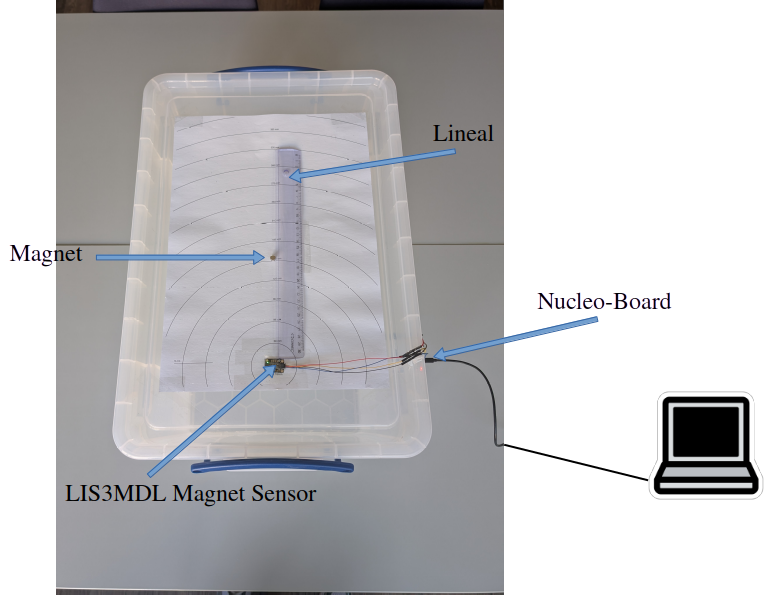

#### Testreihen:

Es wurden drei verschiedene Testreihen durchgeführt, um die Wiederholbarkeit bei Variation der Zeit und bei Variation von Zeit und Ort zu überprüfen.

#### Durchführung einer Testreihe:

Eine Testreihe besteht aus mehreren Stichproben. Jede Stichprobe enthält n=60 Einzelmessungen, mit T0=1s, bei der die magnetische Flussdichte am Magnetsensor gemessen wird.

Die Stichproben unterscheiden sichin der Plazierung des Magneten in x-Richtung des Sensors.

Die Abstände sind 45mm, 60mm, 90mm, 120mm, 130mm, 140mm, 150mm, 160mm, 170mm, 180mm, 210mm, 240mm, 270mm, 300mm.

Eine Positionierung vor 45mm sättigt den Sensor und gibt fehlerhafte Werte aus.

Zwischen 120 mm und 180 mm wurde ein feinerer Abstand verwendet, da Medability in Vorversuchen festgestellt hatte, dass dieser Bereich die Grenze darstellt, bei der ein Magnet noch erkennbar/unterscheidbar ist.

Vor jeder Testreihe wurde eine Stichprobe ohne Magnet gemacht. Der Mittelwert dieser Messung wurde jedem Einzelwert der Messung abgezogen. Das wird gemacht, um die lokalen statischen Offsets aus den Messwerten zu entfernen und die Testreihen miteinander zu vergleichen.

function [measurements, distances, offset_data] = get_measurements(results_folder, do_offset)
    files = dir(fullfile(results_folder, 'mag_data_*'));
    filenames = {files(:).name};
    
    T0 = 1000; % ms
    
    for i=1:numel(filenames)
        if(regexp(filenames{i}, 'mag_data_([a-zA-Z0-9]+)\w+_no_influence.txt'))
            values = readtable(fullfile(results_folder, filenames{i}));
    
            offset_data.x = mean(values.x);
            offset_data.y = mean(values.y);
            offset_data.z = mean(values.z);

            %offset_data

            filenames(i) = [];
            break;
        end
    end
    
    distances = zeros(1, numel(filenames));
    
    for i = 1:numel(filenames)
        tokens = regexp(filenames{i}, 'mag_data_([a-zA-Z0-9]+)\w+_(\d+)mm.txt', 'tokens');
        distances(i) = str2num(tokens{:}{2});
        values = readtable(fullfile(results_folder, filenames{i}));
        
        indices_every_T0 = logical([1; diff(floor((values.timestamp - values.timestamp(1)) / T0))]);
        indices_every_T0 = true(1, numel(values.x));

        if(do_offset)
            tmp = table(values.x(indices_every_T0) - offset_data.x, values.y(indices_every_T0) - offset_data.y, values.z(indices_every_T0) - offset_data.z, values.timestamp(indices_every_T0), 'VariableNames', {'x', 'y', 'z', 'timestamp'});
        else
            tmp = table(values.x(indices_every_T0), values.y(indices_every_T0), values.z(indices_every_T0), values.timestamp(indices_every_T0), 'VariableNames', {'x', 'y', 'z', 'timestamp'});
        end
        measurements{i} = tmp(:, :);
    end
    
    [distances, index] = sort(distances);
    
    measurements = measurements(index);
end

results_folders = {'../../result/LIS3MDL_Besprechungsraum/1', '../../result/LIS3MDL_Besprechungsraum/2', '../../result/LIS3MDL_Sportraum/1'};
[measurements1, distances1] = get_measurements(results_folders{1}, true);
[measurements2, distances2] = get_measurements(results_folders{2}, true);
[measurements3, distances3] = get_measurements(results_folders{3}, true);

function [estimated_mean, standard_deviation] = mean_and_stddev(measurements)
    estimated_mean = zeros(1, numel(measurements));
    standard_deviation = zeros(1, numel(measurements));

    for i = 1:numel(measurements)
        estimated_mean(i) = mean(measurements{i}.z);
        standard_deviation(i) = std(measurements{i}.z);
    end
end

function plot_with_distance(measurements, distances)
    [estimated_mean, standard_deviation] = mean_and_stddev(measurements);

    hold on;

    curve1 = estimated_mean + standard_deviation;
    curve2 = estimated_mean - standard_deviation;
    x2 = [distances, fliplr(distances)];
    inBetween = [curve1, fliplr(curve2)];
    fill(x2, inBetween, '- ', 'FaceColor', uint8([170 170 170]), 'LineStyle', 'none');

    plot(distances, estimated_mean, '*');

    for pos = 1:numel(measurements)-1
        text((distances(pos) + distances(pos + 1)) / 2, (estimated_mean(pos) + estimated_mean(pos + 1)) / 2 + 10 + 15 * mod(pos, 2), ['±' num2str(ceil(abs((distances(pos) - distances(pos + 1)) / (estimated_mean(pos) - estimated_mean(pos + 1)) * max(standard_deviation(pos), standard_deviation(pos + 1)))*10)/10), 'mm'])
    end

    hold off;
end

function norm = measurement_2norm(measurement)
    norm = sqrt(measurement.z.^2 + measurement.y.^2 + measurement.x.^2);
end

#### Mittelwert und Standardabweichung:

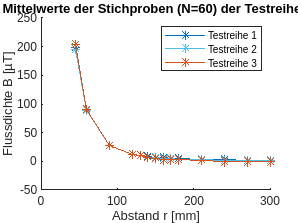

[estimated_mean1, standard_deviation1] = mean_and_stddev(measurements1);
[estimated_mean2, standard_deviation2] = mean_and_stddev(measurements2);
[estimated_mean3, standard_deviation3] = mean_and_stddev(measurements3);

figure
hold on;
plot(distances1, estimated_mean1, "*-", 'Color', "#0072BD");
plot(distances2, estimated_mean2, "*-", 'Color', "#4DBEEE");
plot(distances3, estimated_mean3, "*-", 'Color', "#D95319");
legend('Testreihe 1', 'Testreihe 2', 'Testreihe 3');
title('Mittelwerte der Stichproben (N=60) der Testreihen');
hold off;

xlabel('Abstand r [mm]');
ylabel('Flussdichte B [µT]');

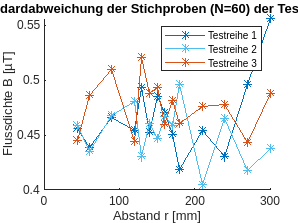


figure
hold on;
plot(distances1, standard_deviation1, "*-", 'Color', "#0072BD");
plot(distances2, standard_deviation2, "*-", 'Color', "#4DBEEE");
plot(distances3, standard_deviation3, "*-", 'Color', "#D95319");
hold off;
legend('Testreihe 1', 'Testreihe 2', 'Testreihe 3');
title('Standardabweichung der Stichproben (N=60) der Testreihen');
xlabel('Abstand r [mm]');
ylabel('Flussdichte B [µT]');

Es lässt sich eine Abhängigkeit der gemessenen Flussdichte mit dem Abstand des Magneten feststellen.

#### Übersetzung in Abstand:

Die Standardabweichungen aller Messungen liegen in einem Bereich von 0.25-0.6 µT. Die Flussdichte steht jedoch in Abhängigkeit des Abstandes.

Um eine Aussage über die Standardabweichung des Abstands zu erhalten, wird für jedes Abstandsintervall eine Sekante gebildet, deren inverse Steigung nun eine näherungsweise Beziehung B(r) innerhalb des Intervalls ergibt. Multipliziert mit dem Maximalwert der Standardabweichung der beiden Stichproben, die das Intervall definieren, ergibt sich Folgendes:

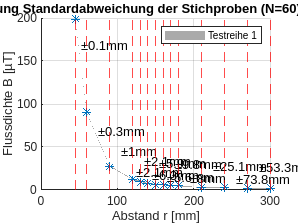

figure
hold on;grid on;

plot_with_distance(measurements1, distances1);
xline(distances1, 'r--');

xlabel('Abstand r [mm]');
ylabel('Flussdichte B [µT]');
title('Übersetzung Standardabweichung der Stichproben (N=60) in Abstand');
legend('Testreihe 1');
hold off;

#### Vergleichbarkeit der Testreihen:

Hierfür wird der F-Test eingesetzt, der die Vergleichbarkeit zwischen den verschiedenen Stichproben überprüft. Die Nullhypothese lautet, dass beide Stichproben normalverteilt mit gleicher Varianz und dementsprechend die Alternativhypothese dass beide Stichproben normalverteilt mit verschiedener Varianz sind. Falls die Nullhypothese nicht abgeleht werden darf (Ergebnis = 0), ist davon auszugehen, dass beide Stichproben aus derselben, normalverteilten Grundgesamtheit stammen und miteinander vergleichbar sind.

for i = 1:numel(measurements1)
    h1(i) = vartest2(measurements1{i}.z, measurements2{i}.z, 'Alpha', 0.05);
    h2(i) = vartest2(measurements1{i}.z, measurements3{i}.z, 'Alpha', 0.05);
    h3(i) = vartest2(measurements2{i}.z, measurements3{i}.z, 'Alpha', 0.05);
end
disp("F-Test:")

F-Test:


FTest = table(distances1', h1', h2', h3', 'VariableNames', {'Abstand', '1 <-> 2', '1 <-> 3', '2 <-> 3'})

FTest = 14×4 table
    Abstand    1 <-> 2    1 <-> 3    2 <-> 3
    _______    _______    _______    _______

       45         0          1          1   
       60         0          1          1   
       90         0          1          1   
      120         1          1          1   
      130         1          1          1   
      140         1          1          1   
      150         1          1          1   
      160         0          1          1   
      170         1          1          1   
      180         1          1          1   
      210         1          1          1   
      240         1          1          1   
      270         1          1          1   
      300         1          1          1   


#### Wiederholbarkeit der Abstandsmessung:

Um zu zeigen, dass der Sensor den Abstand des Magneten innerhalb eines Intervalls [-Δ, Δ] wiederholbar messen kann, wird der TOST-Test angewendet. TOST besteht aus zwei einseitigen t-Tests mit den Nullhypothesen H01: Δ ≤ -Δ und H02: Δ ≥ Δ. Wenn beide Nullhypothesen statistisch abgelehnt werden können, können wir zu dem Schluss kommen, dass der Abstand innerhalb der Grenzen liegt.

Das spätere Produkt von Medability soll innerhalb eines Bereiches 150mm die Position des Magneten zuverlässig berechnen. Für einen ersten sehr konservativen Test setzen wir Δ = 5mm. Da die Messwerte in µT vorliegen approximieren wir Δ wieder mithilfe der Sekantensteigung einer Messung.

addpath("../../thirdparty/TOST");

function [h] = TOST_with_distance(delta, distances, measurements1, measurements2, alpha)
    [estimated_mean1, ~] = mean_and_stddev(measurements1);
    h = zeros(1, numel(distances));
    for i = 1:numel(distances)-1
        delta_microtesla = abs((estimated_mean1(i) - estimated_mean1(i + 1)) / (distances(i) - distances(i + 1)) * delta);
        
        h(i) = TOSTtest2_matlab(measurements1{i}.z, measurements2{i}.z, delta_microtesla);
    end
    
end

delta = 2; % mm
[h1] = TOST_with_distance(delta, distances1, measurements1, measurements2, 0.05);
[h2] = TOST_with_distance(delta, distances1, measurements1, measurements3, 0.05);
[h3] = TOST_with_distance(delta, distances1, measurements2, measurements3, 0.05);


disp('TOST-Test:')

TOST-Test:


TOSTTest = table(distances1', h1', h2', h3', 'VariableNames', {'Abstand', '1 <-> 2', '1 <-> 3', '2 <-> 3'})

TOSTTest = 14×4 table
    Abstand    1 <-> 2    1 <-> 3    2 <-> 3
    _______    _______    _______    _______

       45         1          1          1   
       60         1          1          1   
       90         1          1          1   
      120         0          0          1   
      130         1          0          1   
      140         0          0          1   
      150         0          0          0   
      160         0          0          0   
      170         0          0          0   
      180         0          0          0   
      210         0          0          0   
      240         0          0          0   
      270         0          0          0   
      300         0          0          0   


Das Ergebnis zeigt, dass eine Messung nur bis 130mm innerhalb des Äquvalenzintervalls wiederholbar ist.

Wie konnten die Ungenauigkeiten entstanden sein?

- Kalibrierung nur mit statischen Magnetfeld

- Ungenaue plazierung des Magneten << 5mm

- Ungenauigkeiten im Magneten -> durch Rotation des Magneten leicht verändertes Magnetfeld

Was sind Optionen, um eine bessere Wiederholbarkeit zu erreichen?

- Kalibrierung über bekannte Punkte -> physikalisches Abstandsgesetz zum Magneten muss bekannt sein

- Platzierung in festen Löchern

#### Physikatischer Zusammenhang Abstand und magnetische Flussdichte:

Der Zusammenhang lässt sich mit dem magnetischen Dipolgesetz beschreiben.

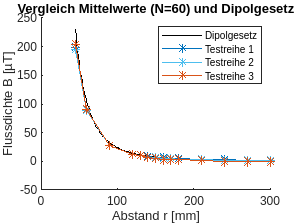

Remanenz = 1.35; % Tesla für N45 Magnet
Magnetisierungrichtung = [0, 0, -1]; % unit vector
Radius = 4e-3; % m
Hoehe = 5e-3; % m

Abstand = 5e-3; % m
Position = [Abstand + Radius, 0e-3, 0e-3];

function B = dipol(Remanenz, Magnetisierungrichtung, Radius, Hoehe, Position)
    magnetischeFeldkonstante = 4 * pi * 1e-7; % N/A²
    Magnetisierung = Remanenz / magnetischeFeldkonstante; % A/m
    moment = Magnetisierungrichtung * Magnetisierung * pi * Radius^2 * Hoehe;

    fun = @(r, m, u0) u0 / (4 * pi) * ((3*r*(m*r')) ./ norm(r)^5 - m ./ norm(r)^3);

    B = fun(Position, moment, magnetischeFeldkonstante) * 1e6;
end

function B_z = dipol_z(distances, Remanenz, Magnetisierungrichtung, Radius, Hoehe)
    B_z = zeros(1, numel(distances));
    for i = 1:numel(distances)
        Position = [distances(i) * 1e-3 + Radius, 0, 0];
        B = dipol(Remanenz, Magnetisierungrichtung, Radius, Hoehe, Position);
        B_z(i) = B(3);
    end
end

figure
hold on;
B_z = dipol_z(45:300, Remanenz, Magnetisierungrichtung, Radius, Hoehe);
plot(45:300, B_z, 'k')
plot(distances1, estimated_mean1, "*-", 'Color', "#0072BD");
plot(distances2, estimated_mean2, "*-", 'Color', "#4DBEEE");
plot(distances3, estimated_mean3, "*-", 'Color', "#D95319");
legend('Dipolgesetz', 'Testreihe 1', 'Testreihe 2', 'Testreihe 3');
title('Vergleich Mittelwerte (N=60) und Dipolgesetz');
hold off;


xlabel('Abstand r [mm]');
ylabel('Flussdichte B [µT]');

#### 1D Koordinaten Transformation:

Für eine 1 D Koordinatentransformation werden 2 Punkte benötigt. Es werden die Mittelwerte für 90mm und 160mm ausgewählt (möglichst weit voneinader entfernt und der Einfluss des Magneten noch groß genug).

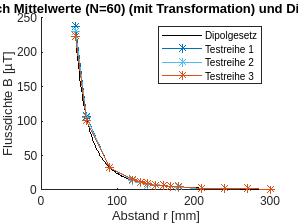

[measurements1, distances1] = get_measurements(results_folders{1}, false);
[measurements2, distances2] = get_measurements(results_folders{2}, false);
[measurements3, distances3] = get_measurements(results_folders{3}, false);

function [a, t] = get_transformation(measurements, distances, i1, i2, Remanenz, Magnetisierungrichtung, Radius, Hoehe)

    x1 = mean(measurements{i1}.z);
    x2 = mean(measurements{i2}.z);
    
    x1_ = dipol_z(distances(i1), Remanenz, Magnetisierungrichtung, Radius, Hoehe);
    x2_ = dipol_z(distances(i2), Remanenz, Magnetisierungrichtung, Radius, Hoehe);

    function [a, t] = transformation(x1, x2, x1_, x2_)
        A = [x1, 1; x2, 1];
        b = [x1_; x2_];
        x = A\b;
        a = x(1);
        t = x(2);
    end

    [a, t] = transformation(x1, x2, x1_, x2_);
end

[a1, t1] = get_transformation(measurements1, distances1, 3, 9, Remanenz, Magnetisierungrichtung, Radius, Hoehe);
[a2, t2] = get_transformation(measurements2, distances2, 3, 9, Remanenz, Magnetisierungrichtung, Radius, Hoehe);
[a3, t3] = get_transformation(measurements3, distances3, 3, 9, Remanenz, Magnetisierungrichtung, Radius, Hoehe);


[estimated_mean1, standard_deviation1] = mean_and_stddev(measurements1);
[estimated_mean2, standard_deviation2] = mean_and_stddev(measurements2);
[estimated_mean3, standard_deviation3] = mean_and_stddev(measurements3);

figure
hold on;
B_z = dipol_z(45:300, Remanenz, Magnetisierungrichtung, Radius, Hoehe);
plot(45:300, B_z, 'k')
plot(distances1, estimated_mean1 * a1 + t1, "*-", 'Color', "#0072BD");
plot(distances2, estimated_mean2 * a2 + t2, "*-", 'Color', "#4DBEEE");
plot(distances3, estimated_mean3 * a3 + t3, "*-", 'Color', "#D95319");
legend('Dipolgesetz', 'Testreihe 1', 'Testreihe 2', 'Testreihe 3');
title('Vergleich Mittelwerte (N=60) (mit Transformation) und Dipolgesetz');
hold off;


xlabel('Abstand r [mm]');
ylabel('Flussdichte B [µT]');

#### Äquvalenztest mit Transformation:

for i = 1:numel(measurements1)
    measurements1{i}.z = measurements1{i}.z * a1 + t1;
    measurements2{i}.z = measurements2{i}.z * a2 + t2;
    measurements3{i}.z = measurements3{i}.z * a3 + t3;
end

for i = 1:numel(measurements1)
    h1(i) = vartest2(measurements1{i}.z, measurements2{i}.z, 'Alpha', 0.05);
    h2(i) = vartest2(measurements1{i}.z, measurements3{i}.z, 'Alpha', 0.05);

F-Test:


    h3(i) = vartest2(measurements2{i}.z, measurements3{i}.z, 'Alpha', 0.05);

FTest = 14×4 table
    Abstand    1 <-> 2    1 <-> 3    2 <-> 3
    _______    _______    _______    _______

       45         1          1          1   
       60         1          0          1   
       90         1          1          0   
      120         1          1          1   
      130         1          1          1   
      140         0          1          1   
      150         1          1          1   
      160         1          1          1   
      170         0          1          1   
      180         1          1          1   
      210         1          1          1   
      240         1          0          1   
      270         1          1          1   
      300         1          1          1   


end
disp("F-Test:")
FTest = table(distances1', h1', h2', h3', 'VariableNames', {'Abstand', '1 <-> 2', '1 <-> 3', '2 <-> 3'})

delta = 2; % mm
[h1] = TOST_with_distance(delta, distances1, measurements1, measurements2, 0.05);
[h2] = TOST_with_distance(delta, distances1, measurements1, measurements3, 0.05);
[h3] = TOST_with_distance(delta, distances1, measurements2, measurements3, 0.05);

TOST-Test:


TOSTTest = 14×4 table
    Abstand    1 <-> 2    1 <-> 3    2 <-> 3
    _______    _______    _______    _______

       45         1          1          1   
       60         1          0          1   
       90         1          1          1   
      120         1          0          0   
      130         1          0          0   
      140         1          0          0   
      150         1          1          1   
      160         1          1          1   
      170         1          1          1   
      180         0          1          0   
      210         0          0          0   
      240         0          0          0   
      270         0          0          0   
      300         0          0          0   



disp('TOST-Test:')
TOSTTest = table(distances1', h1', h2', h3', 'VariableNames', {'Abstand', '1 <-> 2', '1 <-> 3', '2 <-> 3'})

Da durch die Koordinatentransformation auch das Sensorrauschen skaliert wird, lässt sich dadurch auch kein besseres Ergebnis erzielen.

#### Nächste Schritte:

- Einsatz mehrerer Sensoren und Berechnung des Abstandes über Optimierungsproblem